#  HomeWork n.2 2021/22

`matricola: 0124002253`

`Nome: Riccardo Andrea, ` 

`Cognome: Spinosa.`

`Corso DI Laurea: Informatica;`

`Interpolazione`

`Lagrange`

Il fitting di dati è il problema della ricostruzione di un fenomeno continuo Se i dati sono esatti e si vuole ricostruire il fenomeno in modo esatto, allora il problema  del fitting è detto problema di interpolazione. L'insieme F(modello lineare) è costituito da funzioni che sono univocamente determinati da n coefficienti che chiameremo a.

Il primo passo è quello dunque di ricostruire la funzione e poi valutarla.

Per poterlo fare non dobbiamo far altro che risolvere un sistema lineare dove l'incognita è il vettore alpha, B*a=y 

Dove B e y sono noti. Dunque  “la funzione f ricostruisce esattamente il fenomeno campionato  dagli m dati (xi,yi), è che il grafico della funzione f(x) deve passare per tutti i punti (xi,yi), cioè che la  funzione f(x) soddisfi le m equazioni f(xi) = yi, i=1:m. Queste m equazioni sono dette condizioni di  interpolazione di Lagrange. (x) = a1b1(x) + a2b2(x) + … + anbn(x). Un insieme F di tale tipo è detto modello lineare. Ricordiamo che l'obbiettivo dell'interpolazione di Lagrange è calcolare gli n coefficienti alpha. Fissati n nodi il teorema di interpolazione di Lagrange afferma che esiste  un unico polinomio di grado n-1 che interpola n punti.

Da tenere a mente  che il numero delle  equazioni è dato dal numero dei dati, sappiamo che la condizione necessaria affinché un sistema abbia soluzione unica è che il numero  delle equazioni sia uguale al numero delle incognite, cioè che la matrice sia quadrata. Se la Matrice è anche non singolare quindi con determinante != 0  il sistema lineare ha soluzione unica e si ha che la f(x)  così ottenuta è l’unica soluzione del problema di interpolazione (in F).  Scriviamo esplicitamente le n equazioni (condizioni di interpolazione di Lagrange): 

f(x1) = a1b1(x1) + a2b2(x1) + … + anbn(x1) = y1 

f(x2) = a1b1(x2) + a2b2(x2) + … + anbn(x2) = y2

 f(xn) = a1b1(xn) + a2b2(xn) + … + anbn(xn) = yn

Il sistema lineare può essere risolto con Gauss e Gausspivoting. In matlab possono essere utilizzati polifit e polival, e si può risolvere il sistema con B\y. 

Trovati gli n coefficienti a dobbiamo valutare il polinomio in n punti che chiamero gamma. Più è elevato il numero di gamma maggiori saranno le informazioni ricevute e maggiore sarà la precisione del polinomio.Per valutare la funzione si risolveve: f(gamma)=B*a. 

**Hermite**

Se si impongono anche m condizioni sulla  derivata prima della funzione interpolante f, si ha il problema di interpolazione di Hermite. I dati di input di un problema di interpolazione di Hermite sono le m coppie di numeri (xi,yi), che  rappresentano l’ascissa  e l’ordinata  dell’i-simo dato (i-simo punto del piano) e gli m  numeri di, che rappresentano i valori (le pendenze) che devono essere assunti nei nodi dalla derivata  prima della funzione interpolante. Si ricerca, dunque, se esiste, una funzione f(x) che soddisfa le 2m equazioni, dette condizioni di interpolazione di  Hermite: f(xi) = yi, i=1:m f’(xi) = di, i=1:m. Si ottiene da tale interpolazione un sistema di equazioni lineari in cui il  numero delle equazioni è uguale al numero delle incognite e come in Lagrange se la matrice è non singolare ammette soluzione unica.

Il teorema dell’interpolazione di Hermite con polinomi recita:

dati m  punti distinti del piano ed m pendenze, esiste un unico polinomio di grado al più 2m-1 che interpola  tali punti assumendo in essi le pendenze assegnate. Lo scopo è sempre risolvere il sistema lineare, dunque trovare i coefficienti a, e poi valutare la funzione con i gamma. 

**Chebichev**

 se i nodi xi sono equispaziati, al crescere di m avviene uno strano fenomeno: il polinomio  interpolante (di grado m-1) approssima in modo sempre più soddisfacente la funzione g(x) intorno  all’origine, ma in modo sempre meno soddisfacente (oscillazioni di ampiezza crescente) vicino agli  estremi dell’intervallo. Tale fenomeno si risolve:

 i nodi non devono essere  uniformemente distribuiti, ma devono essere scelti in modo da essere più densi vicino agli estremi e  meno nella parte centrale. La scelta sono i nodi di chebichev:

xk = - cos(pi·k/(n-1) k=0 : n-1

Alpha = pi/n-1 --> si divide l'angolo pi in n- angoli uguali, all'aumentare di alpha aumentano i coseni e cosi aumenta il numero di nodi distribuito ai lati.

**Interpolazione a tratti**

Per definire un polinomio a tratti in un intervallo [a,b] bisogna preventivamente definire un insieme  ordinato di m punti di [a,b] detti breakpoints; a e b devono essere breakpoints; ciò significa  suddividere l’intervallo [a,b] in m-1 (sotto-)intervalli, detti celle, che hanno per estremi due  breakpoints consecutivi.  un polinomio a tratti pp(x) di grado k è una funzione definita in [a,b]  che in ogni cella è un polinomio di grado al più k.  In altri termini, pp è una funzione costituita da m-1  pezzi, Il grado di regolarità di pp dipende da come sono attaccati tra loro i vari pezzi che lo compongono.  I polinomi di grado k, si ottengono imponendo la continuità del pp e di  tutte le sue derivate, in tutti i breakpoints. Se, invece, si impone che un polinomio a tratti sia una  funzione continua e che le sue derivate fino alla (k-1)-sima siano continue, allora si ottiene l’insieme  delle spline di grado k.

Le spline Conosciute e maggiormente utilizzate sono quelle di grado 1 e quelle cubiche. . Una spline lineare è una funzione continua in [a,b].  Una spline cubica è una funzione continua in [a,b], con derivata prima e derivata seconda continua.   se si impone che un polinomio a tratti  sia una funzione continua con la sola derivata prima continua, allora si ottiene l’insieme delle  cubiche di Hermite dove  si considera l’insieme dei  nodi (gli xi) come insieme dei breakpoints. Una spline lineare è costituita da m-1 polinomi di primo grado Ti(x)=ai+bi(x-xi), x in [xi,xi+1]. Una spline  lineare è univocamente determinata fissando i valori dei due coefficienti ai, bi in tutte le celle.Le  spline lineari hanno  2(m-1) = 2m-2 incognite da determinare, L1(x1)=y1, L1(x2)=y2, L2(x2)=y2, L2(x3)=y3, L3(x3)=y3..., le condizioni sono tante quanto le incognite. Una spline cubica è costituita da m-1 polinomi di terzo grado si(x)=ai+bi(x-xi)+ci(x-xi) 2+di(x-xi) 3 , con x  in [xi,xi+1].  Quindi, nel problema di interpolazione con spline cubiche ci sono 4(m-1) =  4m-4 incognite da determinare. Imponendo le condizioni di interpolazione, si ottiene: s1(x1)=y1,  s1(x2)=y2, s2(x2)=y2, s2(x3)=y3, s3(x3)=y3, ….. (2m-2 condizioni); Vanno poi aggiunte le condizioni delle derivate dando vita   a un sistema di 4m-6 equazioni in 4m-4 incognite, per ottenere un sistema quadrato vanno aggiunte due condizioni. Se si sceglie spline naturali la prima e ultima hanno derivata seconda =0, se seguiamo la notazione matlab not a knot penultima e seconda hanno derivata =0. Una cubica di Hermite è costituita da m-1 polinomi di terzo grado e è univocamente determinata fissando i valori dei quattro  coefficienti in tutte le celle. il problema di interpolazione con cubiche di Hermite ha  4(m-1) = 4m-4 incognite da determinare.  il suo  grafico non presenta oscillazioni tra due dati consecutivi preservando i dati e si ottiene sistema di 4m-4  equazioni lineari in 4m-4 incognite dove non è presente più derivata seconda continua.

**Curve Parametriche**

Quando parliamo d'interpolazione di curve parametriche non parliamo più d'interpolazione di funzioni ma di vere e proprie curve, per poter svolgere questo punto è importante sapere che una curva parametrica si può scomporre in 2 funzioni diverse in funztione d t(tempo), x(t) ed y(t), infatti otterremo nuovamente la curva unendo le due funzioni. La scelta più semplice è di far variare il parametro  t nell’intervallo [1,m], dove m è il numero dei punti, e di considerare che il punto (xi,yi) corrisponda al  valore t=i del parametro, i=1:m. In questo caso, t è detto parametro ordinale in quanto si ha che t=1  nel primo punto, t=2 nel secondo punto, t=m nell’ultimo punto. Un’altra scelta del parametro (più  efficace della precedente nel caso di punti (xi,yi) non distribuiti uniformemente sulla curva) è di far  variare t nell’intervallo [0, L], dove L è la lunghezza della curva. o il problema dell’interpolazione con curve parametriche è equivalente a  due problemi di interpolazione di Lagrange.

`Punto 1.`

**Definire un dominio **$[a,b]$** ed una funzione composta **$f(x)$** in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc.). Per stabilire un intervallo nel quale **$f$**sia definita e non prensenti punti di discontinuità, utilizzare eventualmente la function MATLAB *****ezplot *****per osservarne il grafico. **

**Definire quindi un insieme di **$m$** punti **$P=\{(x_i,y_i)\}_{i=1}^m$** con **$11 \leq m \leq 21, m \in \mathbb{N}$**. Le ascisse di **$P$** sono linearmente distribuite in **$[a,b]$**, le ordinate sono i corrispondenti valori assunti dalla valutazione di **$f(x)$**.**

Funzioni: f(x) = $x^2  - 1  $  g(x) =   $2e^x + cos(3x^2)$

funrif è data dalle due funziona sopra.

funrif= $(2e^x+cos(3x^2))^2 -1$

load('Dati_HM2.mat');

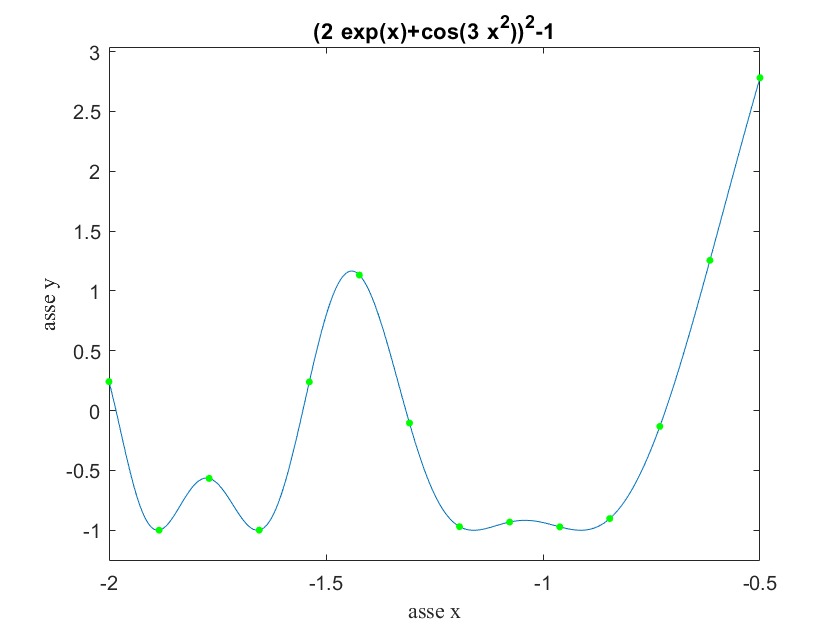

funrif = @(x) (2*exp(x)+cos(3*x.^2)).^2-1;% definisco handler della funzione
a=-2;% estremo sinistro
b=-0.5;% estremo destro
figure (1)
ezplot(funrif,[a,b])% matlab consiglia fplot, lascio ezplot come richiesto dalla traccia
m=14; % dichiato m>10 e <22 
x=linspace(a,b,m); %ascisse linearmente distribuite
P = [x',funrif(x)'];% creo la marice P
hold on
for i=1 : m
    plot(P(i,1),P(i,2),'.','markersize',12,'color','g')% grafichiamo le nostre 0 sul grafico
end
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
hold off

***Spiegazione di ciò che è stato  fatto: ***

Definisco la funzione composta combinando le principali funzioni elementari e definisco un intervallo dove f sia continua. Distribuiamo m punti x,y così da prepararci ai punti successivi.

**1.1. Definire un insieme **$\mathcal{F}$**di funzioni modello polinomiali. Scegliere un'opportuna base così da determinare il polinomio **$p$  $\in$ $\mathcal{F}$** che interpola **$f$** nei nodi **$x_i$**. Costruire e risolvere il relativo sistema lineare **$Ba=y$** (non usare il comando backslash di MATLAB).  Calcolare inoltre l'indice di condizionamento della matrice **$B$**.**

%salvo le x ed y precedenemtente assegnate in due vettori e li traspongo
format long
y=P(:,2);
x=x';%traspongo per coerenza alla teoria
%costruisco La matrice B
for i =1 : m
    for j=1 : m
        B(i,j)=x(i).^(j-1);
    end
end


det(B) %determinante diverso da 0

ans =      3.585712005419255e-32


%il vettore di coefficienti e è 
acof=Sgauss_pivot(B,y) %stampo

acof = 	1.0e+08 *

   0.002956531151031
   0.037867984413039
   0.220123747897686
   0.769175880979670
   1.803142612231811
   2.995435352512196
   3.628695792817173
   3.246313389918214
   2.145220982615003
   1.034422491091675


%calcolo l'indice di condizionamento della matrice
cond(B) 

ans =      9.597687202736225e+13


***Spiegazione di ciò che è stato  fatto: ***

*Utilizzo un doppio ciclo for per costruire la matrice B e calcolo attraverso la funzione Sgauss_pivot() a, calcolo l'indice di condizionamento della matrice attraverso cond() che restituisce un numero >1. più il condizionamento risulta piccolo meglio è considzionata la matrice.*

** 1.2. Valutare il polinomio **$p$** su una griglia di **$N$** punti di valutazione distribuiti casualmente in **$[a,b]$**. Fissare **$N\,\,( 201 \leq N \leq 399)$**. Calcolare l'errore di interpolazione della funzione interpolante scelta al punto precedente.**

n = 270;
xx = a+(b-a)*rand(n,1);
xx = sort(xx);
for j = 1 : m
    for i = 1 : n
        BB(i,j)=xx(i).^(j-1);
    end
end

yy=BB*acof % stampo 

yy =    4.387746036052704
   5.366360247135162
   5.370607078075409
   5.329624235630035
   5.057390928268433
   4.373331665992737
   2.832824409008026
   2.776727199554443
   2.544173359870911
   2.234653174877167


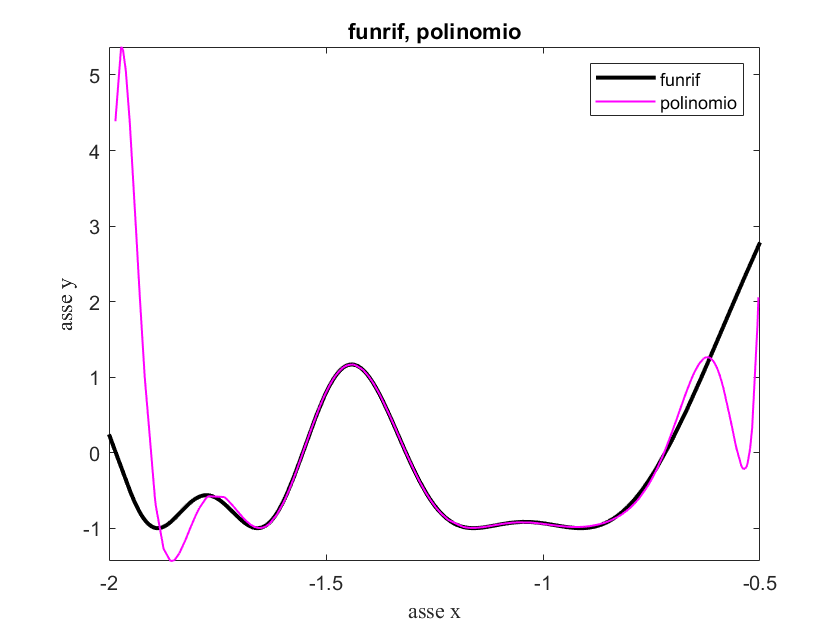

figure(2)
fplot(funrif,[a,b],"color" , 'k','LineWidth',2)
hold on
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
plot(xx,yy,"color" , 'magenta','LineWidth',1)
title('funrif, polinomio'); % da un titolo alla nostra rappresentazione del grafico
legend('funrif','polinomio')
hold off


errore_interpolazione=abs(funrif(xx)-yy)

errore_interpolazione =    4.364232684307515
   5.555138842426239
   5.575027632370379
   5.589612596472503
   5.419766900177135
   4.873630544916854
   3.540378331837611
   3.490684757660596
   3.284086389747376
   3.007720139624392


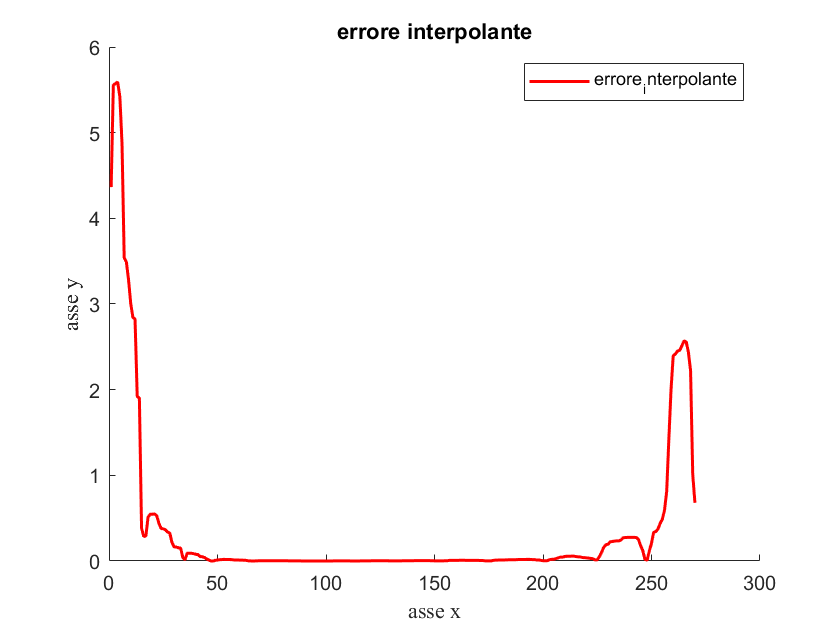

figure(3)
hold on
plot(errore_interpolazione,'Color','r','LineWidth',1.5);%plotto errore e gli assegno il colore rosso
xlabel("asse x",'FontName','Times New Roman')%definisco l'asse x
ylabel("asse y",'FontName','Times New Roman')%definisco l'asse y
title('errore interpolante'); % da un titolo alla nostra rappresentazione del grafico
legend('errore_interpolante')%faccio legenda
hold off

***Spiegazione di ciò che è stato fatto: ***

*Ho definito i gamma per valutare il polinomio, maggiore è il numero di gamma maggiore sarà il numero di informazioni. *

*Ho generato casualmente i gamma con la funzione rand() e li ho successivamente ordinati con un sort(), ho costruito La matrice BB con un doppio ciclo for con le nuove informazioni  e ci siamo calcolati le f(gamma) con una moltiplicazione matrice vettore.*

*ricordiamo che per essere definita tale operazione la matrice ed il vettore devono avere rispettivamente lo stesso numero di colonne e righe. Ci siamo infine calcolati l'errore interpolante e plottato i corrispettivi grafici.*

**1.3. Interpolare i punti **$P$** mediante una spline **$s$** di terzo grado di tipo *****not-a-knot*****.  Valutare l'interpolante ottenuto sulla una griglia di **$N$** punti di valutazione.**

N=500;
xspline=linspace(a,b,N);%creo nuovi gamma nello stesso intervallo dei gamma creati precedentemente
yspline=spline(x,y,xspline);% calcolo la spline, matlab fa automaticamente knot a not
errs=abs(funrif(xspline)'-yspline') % calcolo l'errore

errs =                    0
   0.046537709099854
   0.087658092980304
   0.123627640227088
   0.154715874143685
   0.181194361216930
   0.203335724984450
   0.221412670327303
   0.235697023056993
   0.246458789489232


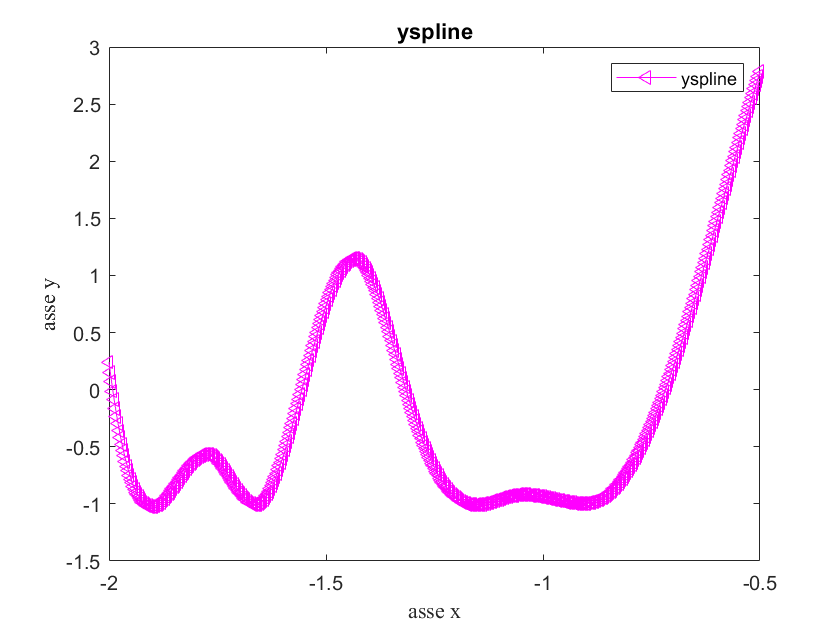

figure(4)
plot(xspline,yspline,'<-','Color','m','LineWidth',0.25);% plotto la spline
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
title('yspline'); % da un titolo alla nostra rappresentazione del grafico
legend('yspline')%faccio legenda

***Spiegazione di ciò che è stato fatto: ***

*Ho creato nuovi gamma nello stesso intervallo dei gamma creati precedentemente  ho calcolo la spline, matlab fa automaticamente knot a not e calcolato l'errore.*

   **1.4. Fissare un valore **$n\,\,( 10 \leq n \leq 19)$** e definire un nuovo insieme di punti **$Q = \{(x_j, y_j)\}_{j=1}^n$** le cui ascisse sono i nodi di Chebyshev in **$[a,b]$** e le cui ordinate sono i valori corrispondenti assunti da **$f(x)$**. Costruire il polinomio interpolante i punti **$Q$** e valutarlo sulla griglia di valutazione generata al punto 1.2.**

(a+b)/2+0.5*(b-a)-coseno(k*pi)/(n-1)

val_n=15;
k=0:(val_n-1);
xc=-cos((k*pi)/(val_n-1));
xc=xc';
xcheb=(a+b)/2+0.5*(b-a)*xc; %calcolo i nodi sull'intervallo
diff(xcheb)%restituisce la differenza tra la coppia dei valori

ans =    0.018804065863632
   0.055469283209554
   0.089353039075792
   0.118756260456972
   0.142204547055882
   0.158522103870933
   0.166890700467236
   0.166890700467236
   0.158522103870933
   0.142204547055882


funzione=@(x,j) x.^(j-1);
ycheb=funrif(xcheb);% inserisco  le y dei nodi in un vettore
Q = [xcheb',ycheb'];% creo la marice Q contenente le ascisse ed ordinate come richeisto dalla traccia

for j=1 : val_n 
    Bcheb(:,j)=funzione(xcheb,j);
end
alphacheb=Sgauss_pivot(Bcheb,ycheb);
for j = 1 : val_n
    for i = 1 : n %% numero nodi di gamma del punto 1.2
        BBcheb(i,j)=xx(i).^(j-1);
    end
end
yycheb= BBcheb*alphacheb

yycheb =    0.023549854755402
  -0.189590930938721
  -0.205367684364319
  -0.261444866657257
  -0.364856421947479
  -0.503875136375427
  -0.710493624210358
  -0.716797292232513
  -0.742283582687378
  -0.774666190147400


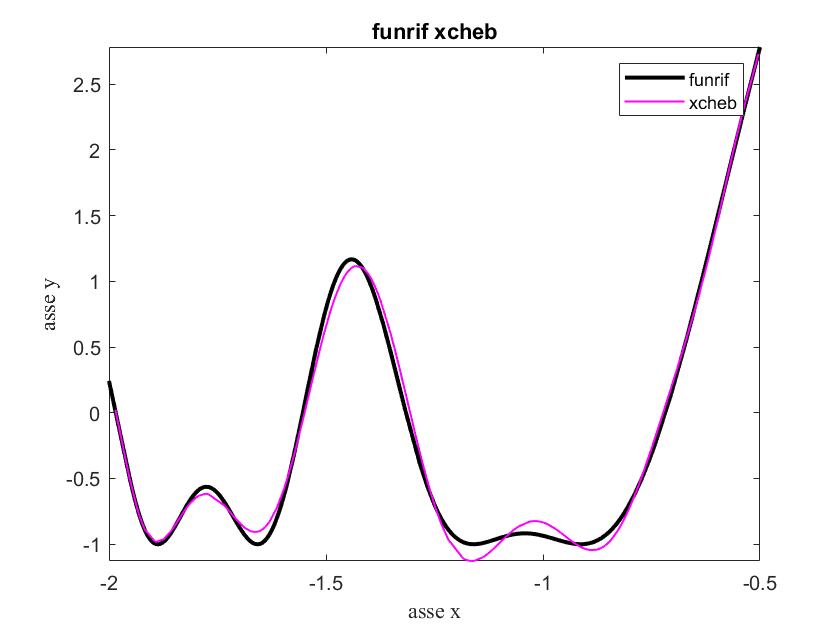

figure(5)
fplot(funrif,[a,b],"color" , 'k','LineWidth',2)
hold on
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
plot(xx,yycheb,"color" , 'magenta','LineWidth',1)
title('funrif xcheb'); % da un titolo alla nostra rappresentazione del grafico
legend('funrif','xcheb')
hold off

***Spiegazione di ciò che è stato fatto: ***

*Ho distribuito i nodi di chebichev ai lati così da ridurre l'errore ai lati nelle oscillazioni, successivamente ho costruito il polinomio interpoante*

**1.5. Infine, mostrare graficamente l'andamento dell'errore di interpolazione. Confrontare numericamente l'errore con quello ottenuto al punto 1.2.**

%calcolo l'errore
errcheb=abs(funrif(xx)-yycheb) 

errcheb =    0.000036503010213
   0.000812335647643
   0.000947130069349
   0.001456505814789
   0.002480450038777
   0.003576257451310
   0.002939701380773
   0.002839734126360
   0.002370552810913
   0.001599225400174


Confronto numericamente l'errore numericamente  ottenuto con quello del punto 1.2

%da notare come l'errore di cheb sia nettamente più piccolo dell'errore  di interpolazione
[norm(errcheb,1) norm(errore_interpolazione,1)]

ans =   14.665925465588851  98.804935665601619


% la norma infinito restituisce l'errore nel punto più alto
[norm(errcheb,'inf') norm(errore_interpolazione,'inf')]

ans =    0.144986921880156   5.589612596472503



% come esperimento personale lascio la differenza tra i due vettori di  errore 
% noto che sono distanti ai laterali e simili al centro 
differenza_errore=abs(errcheb-errore_interpolazione)

differenza_errore =    4.364196181297302
   5.554326506778596
   5.574080502301030
   5.588156090657714
   5.417286450138358
   4.870054287465544
   3.537438630456839
   3.487845023534236
   3.281715836936463
   3.006120914224218


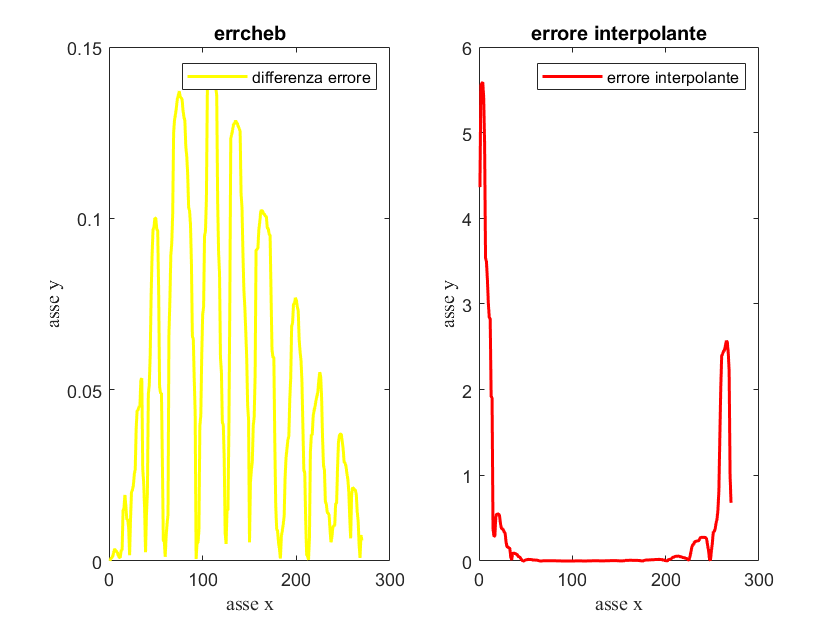


figure(6)
hold on
subplot(121),plot(errcheb,'Color','y','LineWidth',1.5);%plotto errore
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
title('errcheb'); % da un titolo alla nostra rappresentazione del grafico
legend('differenza errore')%faccio legenda 
hold off
hold on
subplot(122),plot(errore_interpolazione,'Color','r','LineWidth',1.5)
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
title('errore interpolante'); % da un titolo alla nostra rappresentazione del grafico
legend('errore interpolante')%faccio legenda 
hold off
hold on

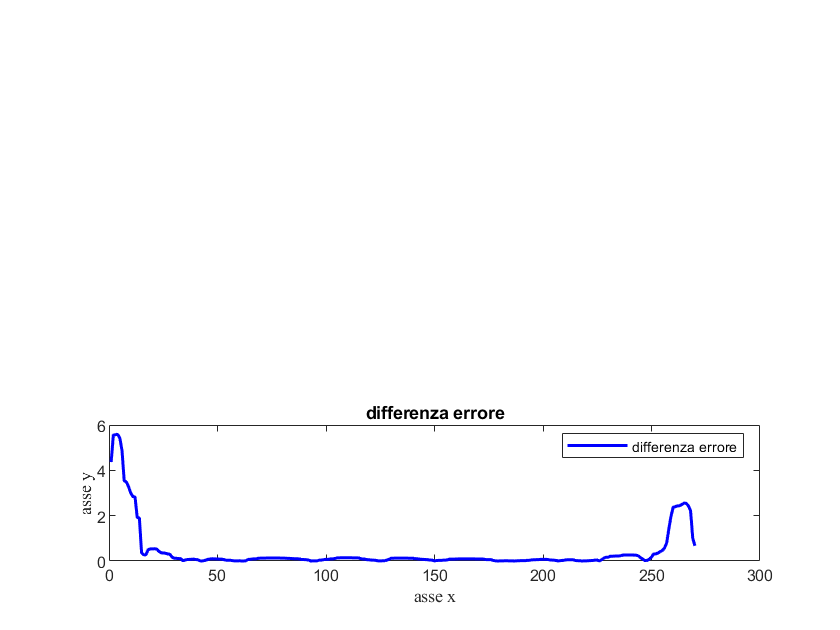

subplot(313),plot(differenza_errore,'Color','b','LineWidth',1.5);%plotto errore
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
title('differenza errore'); % da un titolo alla nostra rappresentazione del grafico
legend('differenza errore')%faccio legenda 
hold off

***Spiegazione di ciò che è stato fatto: ***

*Ho plottato gli errori precedenteente calcolati.*

**1.6. Considerare il poligono di **$N$**vertici costituito dai valori della curva parametrica interpolata al punto (1.2) e, tramite il comando **`fill, `**visualizzare in una figura tale poligono colorato con un colore generato da una terna RGB. **

**(NON OBBLIGATORIO)**

clear H
clear ax
clear ay
figure(20)
hold on
%calcolo punto medio delle y.
altezza=(max(yy)+min(yy))/2;
% riempo la  prima colonna della matice delle x create nel punto 1.2
H(:,1)=xx;
% riempo la seconda colonna della matice delle y create nel punto 1.2
H(:, 2)=yy;
%stampo h per controlarne i valori
H

H =   -1.985296621605407   4.387746036052704
  -1.972080837910421   5.366360247135162
  -1.971113783878788   5.370607078075409
  -1.967666169194755   5.329624235630035
  -1.961213793375291   5.057390928268433
  -1.952116055744032   4.373331665992737
  -1.936553303128186   2.832824409008026
  -1.936010216097427   2.776727199554443
  -1.933751642356008   2.544173359870911
  -1.930712665502678   2.234653174877167


%ordino i punti in base alle y
for j = 0 : length(yy)-1
    for i = 1: length(yy)-j-1
      if H(i,2)>H(i+1,2)
                temp = H(i,2);
                H(i,2) = H(i+1,2);
                H(i+1,2) = temp;
                temp = H(i,1);
                H(i,1) = H(i+1,1);
                H(i+1,1) = temp;
        end
    end
end
% ordino le i punti rispetto alle x
% in ordine crescente se l'ordiata è maggiore del valore di altezza
% in ordine decrescente se invece è minore
for j = 0 : length(yy)-1
    for i = 1: length(yy)-j-1
        if H(i,2)>altezza% se maggiori della altezza
            if H(i,1)>H(i+1,1)
                temp = H(i,1);
                H(i,1) = H(i+1,1);
                H(i+1,1) = temp;
                temp = H(i,2);
                H(i,2) = H(i+1,2);
                H(i+1,2) = temp;
            end
        else%se minori dell'altezza
            if H(i,1)<H(i+1,1) && H(i+1,2)<altezza
                temp = H(i,1);
                H(i,1) = H(i+1,1);
                H(i+1,1) = temp;
                temp = H(i,2);
                H(i,2) = H(i+1,2);
                H(i+1,2) = temp;
            end

        end
    end
end
% I punti nella matrice sono ordinati in modo da ottenere un poligono con
% al più due lati che si intersecano
% controllo e stampo La nuova H
H

H =   -0.505765833054696   1.699135561913071
  -0.518037948153752   0.328341202050158
  -0.522835644544085   0.050948571255791
  -0.528644545929712  -0.144113377543185
  -0.531306301349162  -0.191396258158033
  -0.537797499222664  -0.219863858688932
  -0.540562498789048  -0.201764237578548
  -0.540899172380324  -0.198540397123459
  -0.542321010516059  -0.182702602520955
  -0.543111777224891  -0.172421414297297


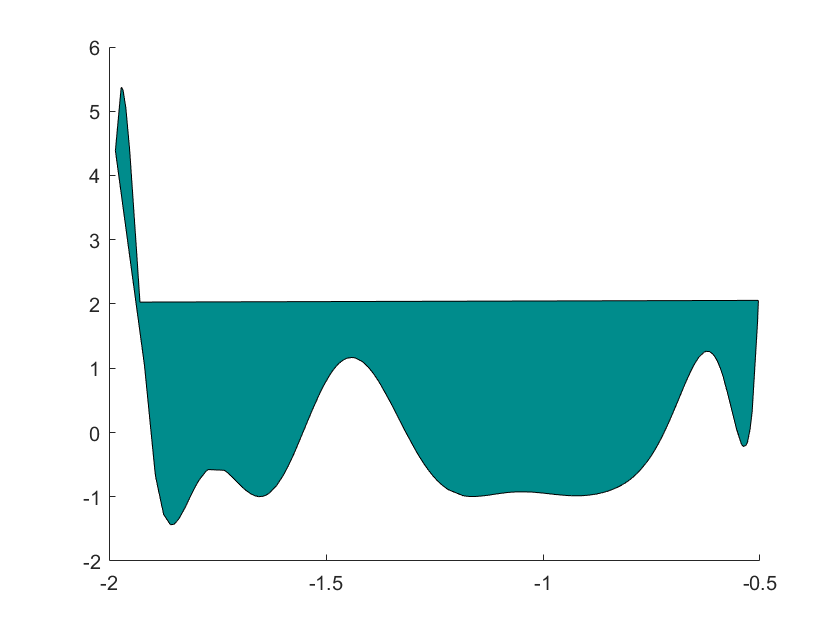

% inserisco prima e secoda colonna in due vettori
ax=H(:,1);
ay=H(:,2);


fill(ax,ay,[0 0.55 0.55])%%eseguo la fill

hold off

***Spiegazione di ciò che è stato fatto: ***

*I punti sono stati inizialmente divisi in due gruppi: il primo composto dai punti con ordinata inferiore al punto medio delle y, l secondo da quelli con ordinata maggiore (ciò è stato ottenuto semplicemente ordinando i punti in base al valore dell'ordinata)*

*I punti sono stati ordinati rispetto al valore delle ascisse. I punti del primo gruppo sono stati ordinati con ordine decrescente, quelli del secondo gruppo con ordine crescente. In questo modo i punti vengono uniti dalla funzione fill procedendo in senso antiorario*

 2.** Interpolazione di curve parametriche**

**Si considerino le seguenti curve parametriche:**

**         1. **$x = 4\sin\Big(\frac{1}{4}t\Big)\quad\quad y = 1 - 2\cos^2\Big(\frac{1}{4}t\Big)\quad\quad -52\pi \leq t \leq 34\pi$

**         2. **$x = 2e^t\quad\quad y = \cos(1+e^{3t})\quad\quad  0 \leq t \leq \frac{3}{4}$

**         3. **$x = t\cos(t)\quad\quad y = t\sin(t)\quad\quad -2\pi \leq t \leq 2\pi$

**         4. **$x = \cos t
 + \frac{1}{4}\cos(8t)\quad\quad y = \sin t + \frac{1}{4}\sin(8t)\quad\quad 0\leq t \leq 2\pi$

**Scegliere una di tali curve e campionarla in **$n$** punti **$P=\{(x_i,y_i)\}_{i=1}^n$**, corrispondenti a **$n$** punti **$t_i$** equispaziati nell'intervallo **$[a,b]$** in cui varia il parametro **$t$** (fissare **$20<n<30$**). **

scelgo il punto 3: $x = t\cos(t)\quad\quad y = t\sin(t)\quad\quad -2\pi \leq t \leq 2\pi$

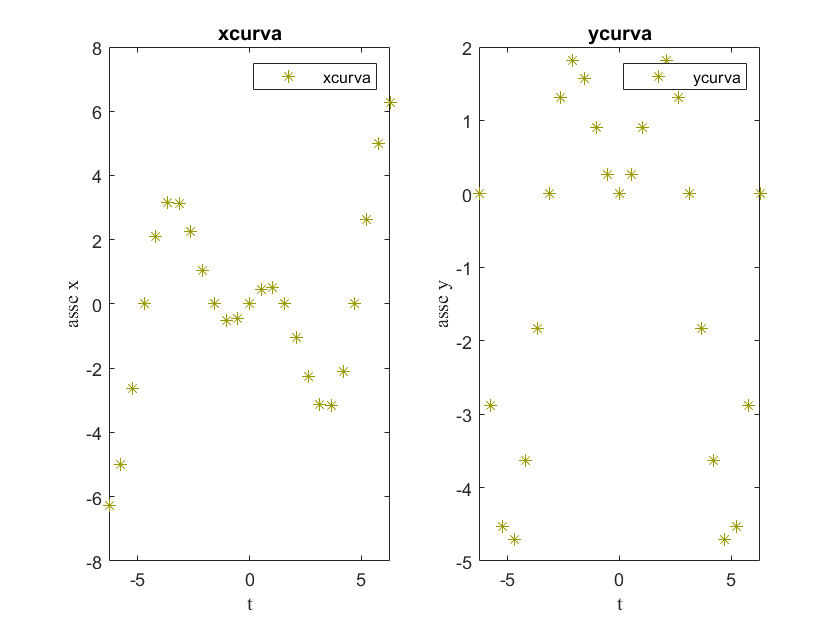

nc=25; % fisso n
t=linspace(-2*pi,2*pi,25);% creo il parametro t che varia nell'intervallo scelto
t=t';
xcurva=t.*cos(t); % essendo t precedentemente trasposto esce anch'esso trasposto
ycurva=t.*sin(t); % essendo t precedentemente trasposto esce anch'esso trasposto
figure(7)
subplot(121),plot(t,xcurva,'*','color','#999900','MarkerSize',6)
hold on
xlabel("t",'FontName','Times New Roman')
ylabel("asse x",'FontName','Times New Roman')
title('xcurva'); % da un titolo alla nostra rappresentazione del grafico
legend('xcurva')%faccio legenda 
hold off
subplot(122),plot(t,ycurva,'*','color','#999900','markersize',6)
hold on
xlabel("t",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
title('ycurva'); % da un titolo alla nostra rappresentazione del grafico
legend('ycurva')%faccio legenda 
hold off

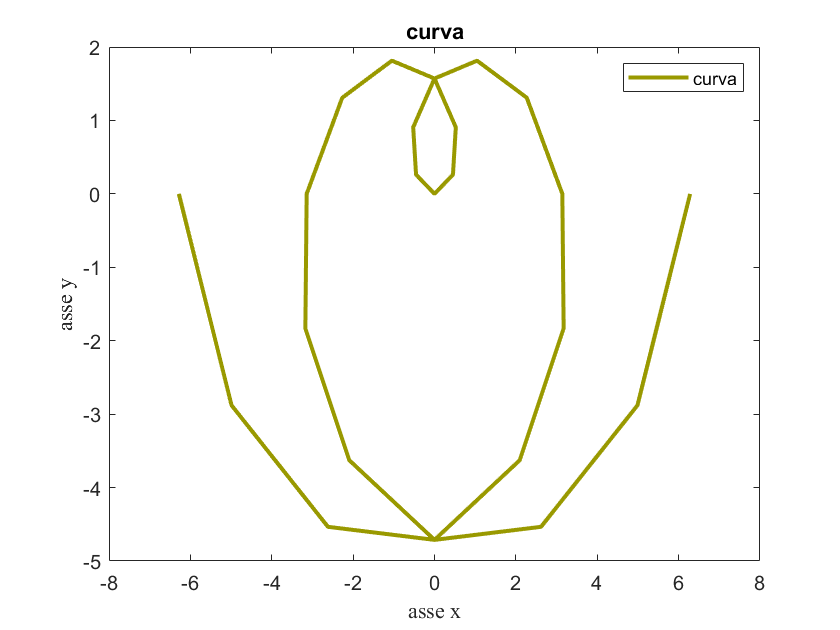

figure(8)
plot(xcurva,ycurva,'color','#999900','LineWidth',2)
xlabel("asse x",'FontName','Times New Roman')
ylabel("asse y",'FontName','Times New Roman')
title('curva'); % da un titolo alla nostra rappresentazione del grafico
legend('curva')%faccio legenda 

   ***Spiegazione di ciò che è stato fatto: ***

Ho creato il parametro t che varia nell'intervallo scelto attraverso linspace e successivamente ho plottat i punti da ricostruire e la sua curva.

**  2.1. costruire due spline parametriche **$p_x$** e **$p_y$** che interpolino rispettivamente i punti **$(t_i,x_i)$** e i punti **$(t_i, y_i)$**  (**$i = 1,\ldots, n$**);**


i=1 : nc;
splinecurvax=spline(t(i),xcurva(i));
splinecurvay=spline(t(i),ycurva(i));


  ***Spiegazione di ciò che è stato fatto: ***

*Ho costruito le spline delle curve attraverso le funzioni matlab.*

**   2.2.  valutare le spline parametriche su una griglia fitta opportuna e mostrare il grafico della curva parametrica interpolata.**

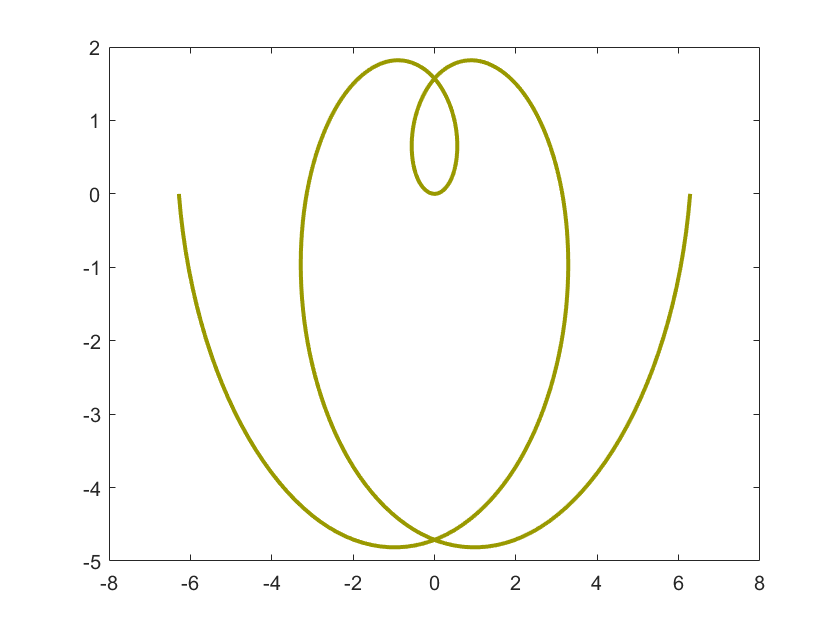

gammacurva= linspace(-2*pi,2*pi,300)';
% calcolo le spline
curvax=ppval(splinecurvax,gammacurva);
curvay=ppval(splinecurvay,gammacurva);
figure(9)
plot(curvax,curvay,'-r','color','#999900','LineWidth',2)

     ***Spiegazione di ciò che è stato fatto: ***

*Calcolato le spline con ppval e plottato la curva interpolante.*

** 2.3.  Ripetere i punti (2.1) e (2.2) su un insieme di **$m=40$** punti **$S = \{(x_j,y_j)\}_{j=1}^m$** le cui ascisse ed ordinate sono valori ottenuti dall'utilizzo del comando **`ginput`** usato su una immagine a propria scelta oppurtunamente caricata (usare **`imread). `**Le coordinate devono essere estese aggiungendo in coda un punto fittizio uguale al primo punto, in modo tale che **`x`** e **`y`** siano i vettori delle coordinate dei vertici di un poligono (chiuso). **

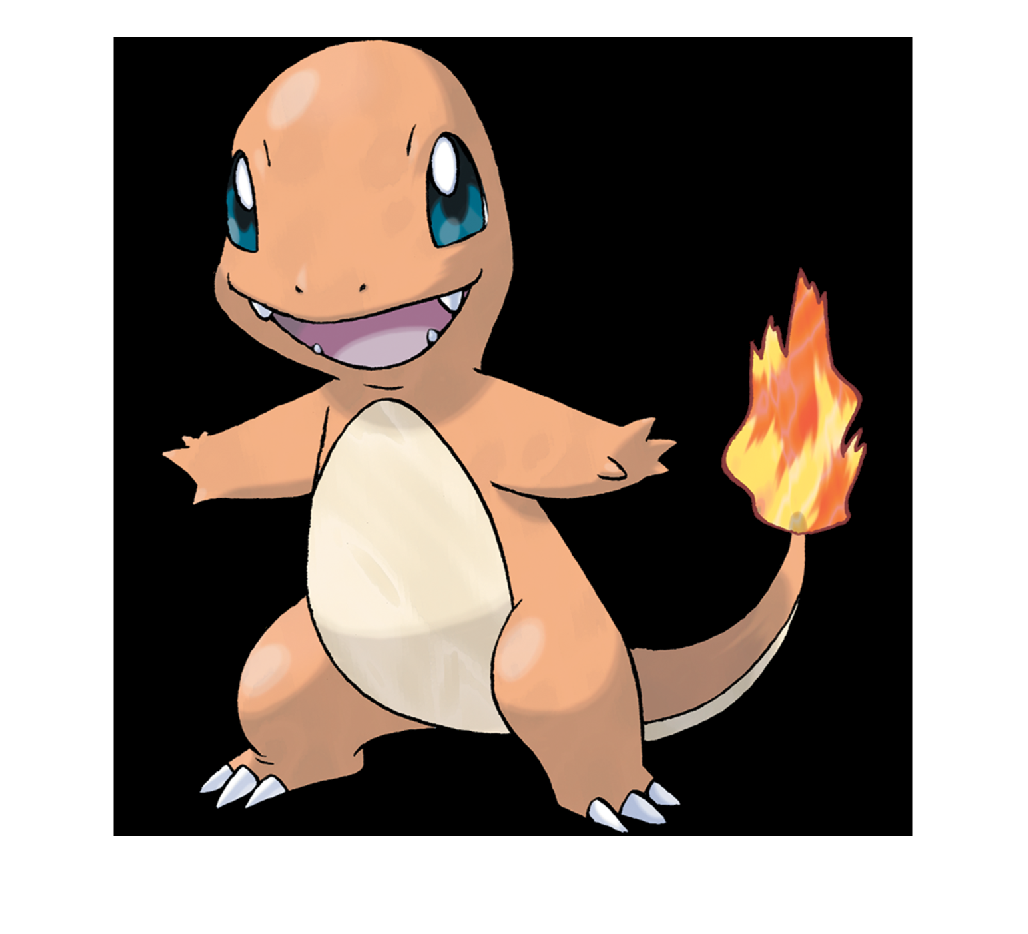

IMG=imread('Charmander.png');
imshow(IMG)

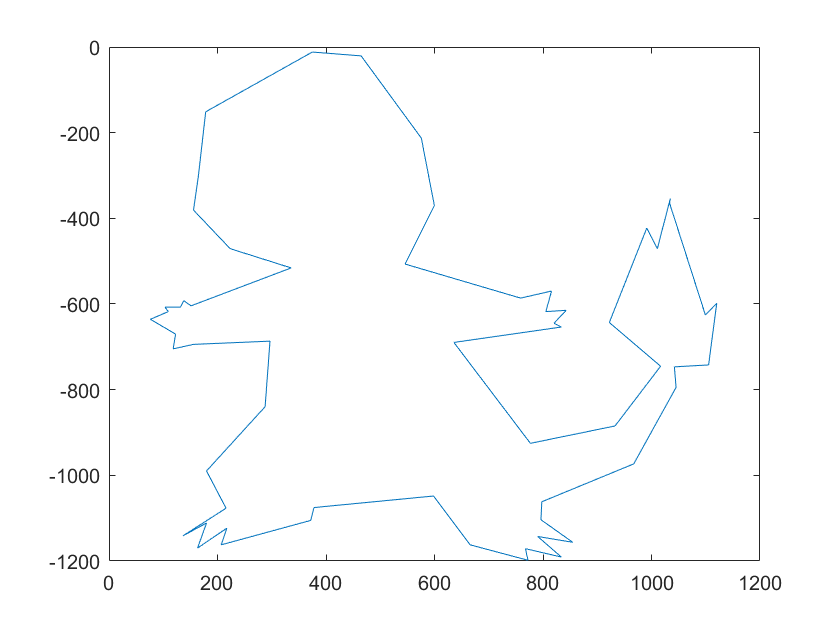


%[imgx,imgy]=ginput(60);
imgx(end+1)=imgx(1);
imgy(end+1)=imgy(1);
figure(10)
plot(imgx,-imgy)   % risolvo il problema degli assi inserendo un meno alle y così da non plottarmela rovesciata

         ***Spiegazione di ciò che è stato fatto: ***

 Ho ottenuto le ascissi con il comando `ginput` caricando l'immagine imread, ho collegato primo ed ultimo punto per ottenere un poligono chiuso.

**2.4. Calcolare il perimetro del poligono ottenuto al punto precedente tramite un'opportuna function che sarà allegata in fondo al file **`.mlx`

per_poligono=perimetro(imgx,imgy)

per_poligono =      6.417400328941360e+03


      ***Spiegazione di ciò che è stato fatto: ***

*Ho calcolato il perimetro calcolando la distanza tra due punti su ogni lato e ne ho fatto la sommatoria*

** 2.5. Ricostruire inoltre la curva parametrica passante per i punti definiti al punto (2.3) mediante le cubiche di Hermite (non spline cubiche). Calcolare la norma infinito del vettore contenente le ordinate assunte dalla valutazione della cubica di Hermite.**

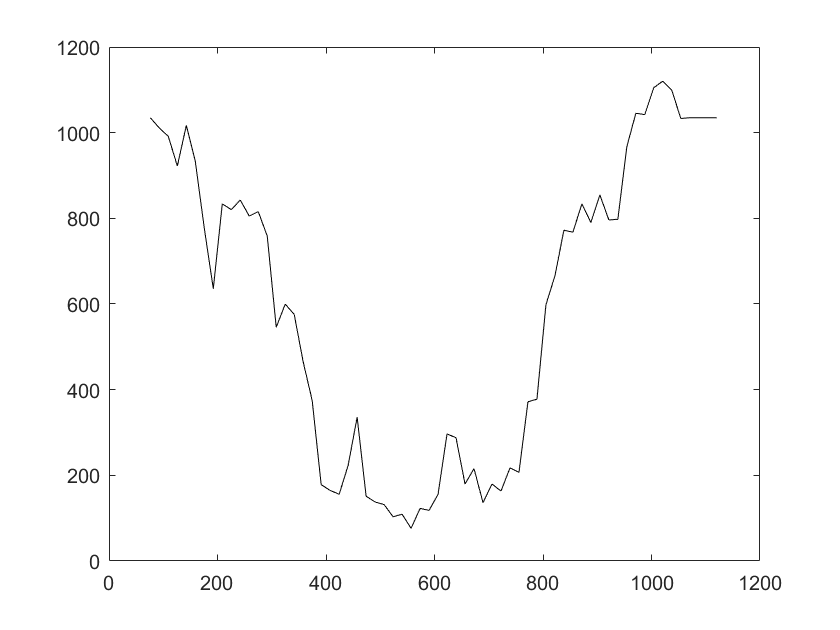

gt=linspace(min(imgx),max(imgx),length(imgx));
gt=gt';
figure(11)
plot(gt,imgx,'color','k'); % plottiamo la funzione in base al tempo

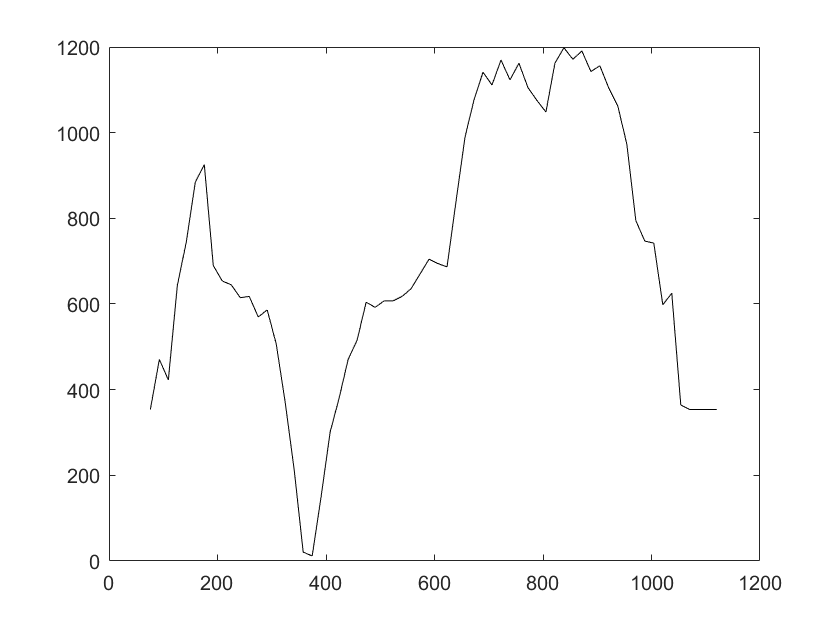

figure(12)
plot(gt,imgy,'color','k'); % plottiamo la funzione in base al tempo

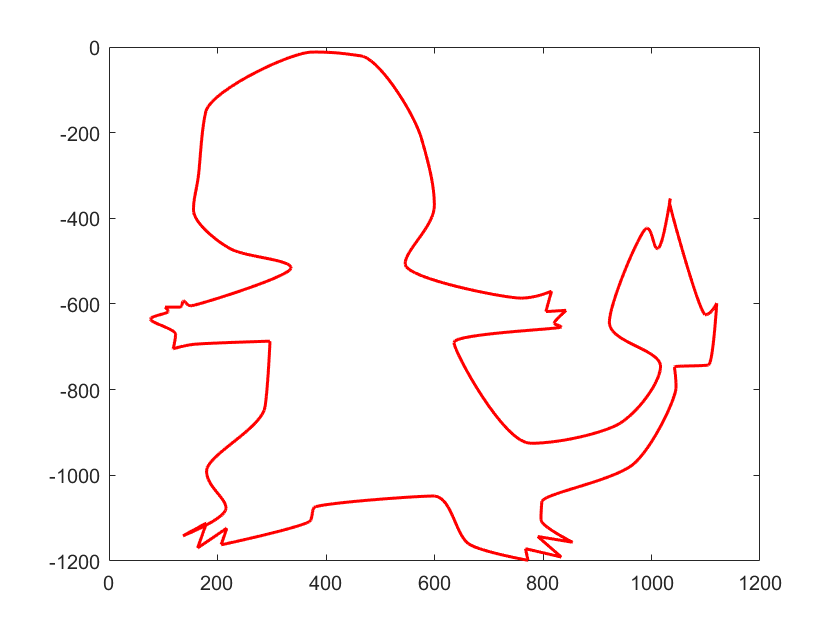

gg=linspace(min(imgx),max(imgx),1000);
%creo la spline di hermite
xxherm=pchip(gt,imgx,gg);
yyherm=pchip(gt,imgy,gg);
figure(13)
plot(xxherm,-yyherm,'color','r','LineWidth',1.5)%plottiamo la spline di hermite

%calcolo l'errrore in norma infinito
norm(yyherm,'inf')

ans =      1.198211422225732e+03


  ***Spiegazione di ciò che è stato fatto: ***

*Ho tracciato il grafico e ricostruito ascisse ed ordinate in funzioni del tempo ed ho ricostruito attraverso la spline di hermite l'immagine caricata definendo i valori gamma su cui costruirla*

**3. Approssimazione**

**Scaricare il dataset dell'andamento del covid da **[**https://github.com/pcm-dpc/COVID-19**](https://github.com/pcm-dpc/COVID-19)

**Caricare il dataset in matlab utilizzando il comando **`readtable`**.**

**Generare un insieme di punti **$C=\{(t_i,y_i)\}_{i=1}^n$** le cui ascisse il tempo **$t_1,t_2,\ldots,t_n$**. I valori sono estratti dalla tabella precedentemente caricata. Scegliere una colonna a piacere che descrive un attributo della tabella.**

** Scegliere inoltre **$5 \leq n \leq 11$.

dataset = readtable ("COVID-19-master/dati-andamento-nazionale/dpc-covid19-ita-andamento-nazionale.csv")

dataset = 843×24 table
           data             stato     ricoverati_con_sintomi    terapia_intensiva    totale_ospedalizzati    isolamento_domiciliare    totale_positivi    variazione_totale_positivi    nuovi_positivi    dimessi_guariti    deceduti    casi_da_sospetto_diagnostico    casi_da_screening    totale_casi    tamponi    casi_testati         note         ingressi_terapia_intensiva    note_test    note_casi    totale_positivi_test_molecolare    totale_positivi_test_antigenico_rapido    tamponi_test_molecolare    tamponi_test_antigenico_rapido
    ___________________<

t non mi è chiaro cosa sia, lascio intendere siano gli istanti di tempo

dim=randi([5 11],1,1)% scelgo n randomicamente

dim =      7


j=1: dim;
C(j,2)=dataset.terapia_intensiva(j);% 2 colonna inserisco i valori su n righe
C(j,1)=rand(1,1)+j;% % 1 colonna inserisco gli istanti su n righe
C

C = 	1.0e+02 *

   0.013981308795313   0.260000000000000
   0.023981308795313   0.350000000000000
   0.033981308795313   0.360000000000000
   0.043981308795313   0.560000000000000
   0.053981308795313   0.640000000000000
   0.063981308795313   1.050000000000000
   0.073981308795313   1.400000000000000
   0.089705985250866   1.660000000000000
   0.099705985250866   2.290000000000000
   0.109705985250866   2.950000000000000


   ***Spiegazione di ciò che è stato fatto: ***

*Ho generato la matrice C inserendo i dati richiesti dalla traccia, in una ho semplicemente estrapolati i valori della colonna scelta e nell'altra ci ho inserito valori randomici che definivano t*

** 3.1 Costruire e valutare, su una griglia fitta di almeno 100 punti, utilizzando i metodi studiati, la retta dei minimi quadrati approssimante i dati.**

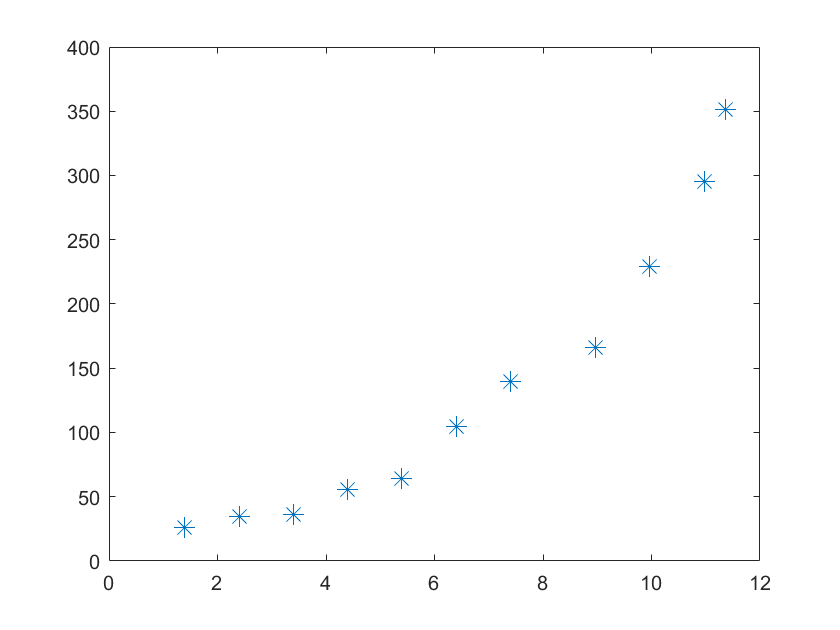

%definisco la retta dei minimi quadrati che vogliamo approssimare
xminquad=C(:,1);
yminquad=C(:,2);
figure(14)
plot(xminquad,yminquad,'*','markersize',10)

Bminquad=[funzione(xminquad,1),funzione(xminquad,2)];
% ci siamo trovati coefficienti
aminquad=(Bminquad'*Bminquad)\(Bminquad'*yminquad);
yyminquad=Bminquad*aminquad;
gammaminquad=linspace(min(xminquad),max(xminquad),100)';%% definiamo la griglia dei 100 valori
for j = 1 : 2
    for i = 1 : length(gammaminquad)
        BBminquad(i,j)=gammaminquad(i).^(j-1);
    end
end
yyyminquad=BBminquad*aminquad

yyyminquad = 	1.0e+02 *

  -0.210383873526481
  -0.179565017150430
  -0.148746160774379
  -0.117927304398328
  -0.087108448022277
  -0.056289591646226
  -0.025470735270175
   0.005348121105876
   0.036166977481927
   0.066985833857978


** 3.2. Mostrare graficamente sia il polinomio di primo grado approssimante che i punti approssimati ed evidenziare sul grafico gli scostamenti.**

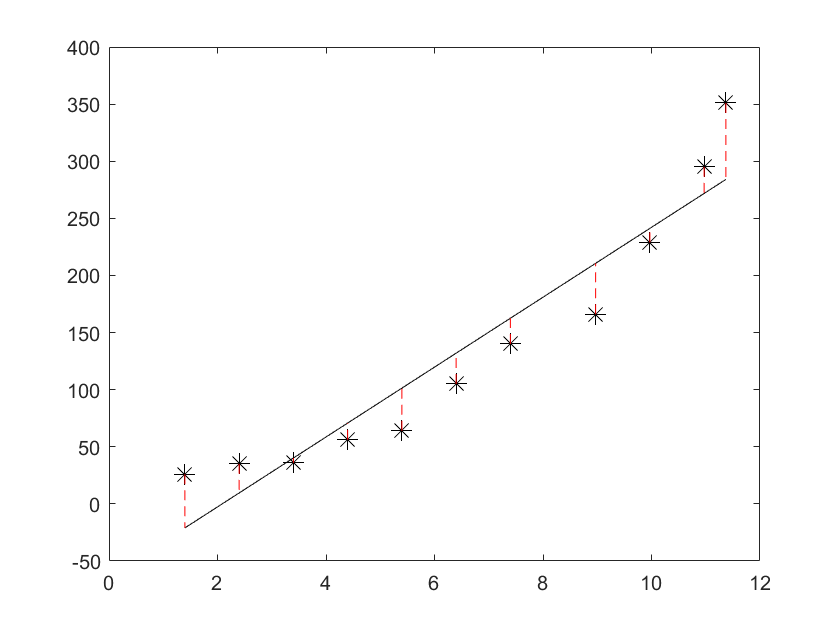

figure(15)% nuova figura
plot(xminquad,yminquad,'*','markersize',10,'color','k')% plotto i punti della retta da approssimare
hold on
plot(gammaminquad,yyyminquad,'color','k')% plotto la retta dei minimi quadrati
for i=1 : length(xminquad)
    plot([xminquad(i) xminquad(i)],[yminquad(i) yyminquad(i)],'--','color', 'r')
end
hold off

        ***Spiegazione di ciò che è stato fatto: ***

*Ho calcolato la retta dei minimi quadrati ricostruendo la matrice BBminquad con un doppio ciclo for calcolandomi i coefficienti e risolvendo le y con BBminquad*aminquad. Ho plottato infine la retta dei minimi quadrati.*

**3.3. Ripetere il punto precedente variando il grado del polinomio approssimante nell'intervallo tra 2 e 10. Mostrare tutte le curve approssimanti ottenute sullo stesso grafico.**


figure(16) % salvo nella f
plot(xminquad,yminquad,'*','markersize',10,'color','k')% plotto i punti della retta da approssimare
  hold on

% utilizzo 3 cicli for i due interni creeranno il polino il ciclo esterno definisce il grado.
 for k =3 : 9
    for j=1 : k
        for i=1 : length(gammaminquad)
            BBB(i,j)=gammaminquad(i).^(j-1);
        end
    end
    aaminquad=(BBB'*BBB)\(BBB'*yyyminquad);
    yyyyminquad(:,k)=BBB*aaminquad;%% matrice dove salvo i vettori
    plot(gammaminquad,yyyyminquad)% plotto la retta dei minimi quadrati
 end

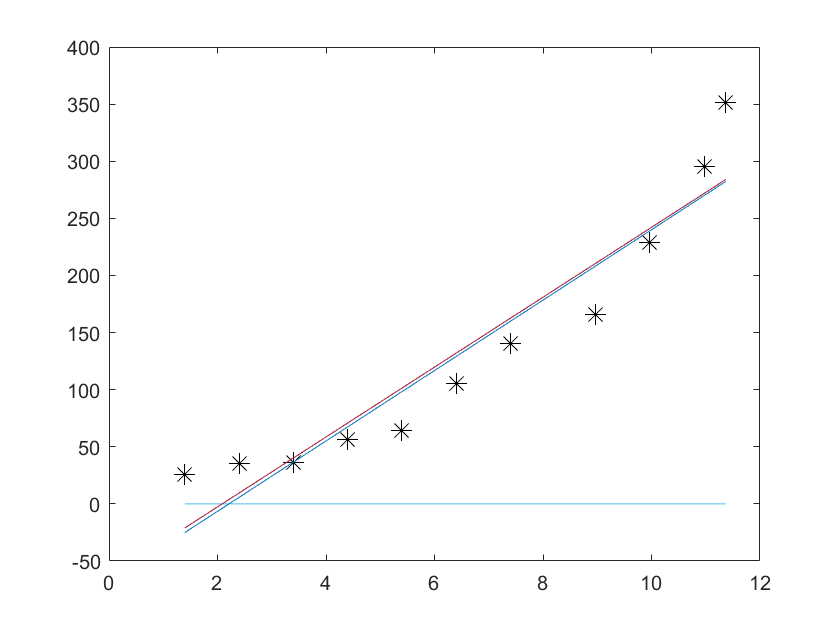

hold off

   ***Spiegazione di ciò che è stato fatto: ***

*Punto più complicato a mio parere dell'homework. Ho utilizzato tre cicli for per costruire ogni plonomio di grado k, i warning mi avvisano che i risultati possono non essere del tutto accurati.*

**  3.4. Valutare il residuo in norma due per ognuna delle curve precedentemente ottenute.**

%stampo vettore contente i residui dei polinomi calcolati prima
for i=1 : 8
    vettore_residui=norm(yyyyminquad(:,i),2)
end

vettore_residui =      0


vettore_residui =      1.567564986541906e+03


vettore_residui =      1.587778540102782e+03


vettore_residui =      1.587778540102782e+03


vettore_residui =      1.587778540102782e+03


vettore_residui =      1.587778540102782e+03


vettore_residui =      1.587778540102782e+03


vettore_residui =      1.587778540102782e+03


   ***Spiegazione di ciò che è stato fatto: ***

*Abbiamo calcolato il vettore dei residui per ogni polinomio creato in norma due. essendo piu polinomi dove ogni vettore y risulta in una colonna della matrice yyyyminquad abbiamo tutilizzato un ciclo for dove scorriamo tutte le righe ed al passo i le colonne.*

**4.1. Definire un dominio **$[a,b]$** ed una funzione composta **$f(x)$** in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc etc). La funzione deve essere definita, positiva e continua in **$[a,b]$**. Usare la funzione **`ezplot`** per stabilire l'intervallo **$[a,b]$**; **


$$f(x)=\frac{1}{(x-1)}$$



$$g(x)=\sqrt{x}$$



$$H=f*g$$



$$f(x)=\frac{1}{\sqrt{x}-1}$$


definita in:


$$ [0;1[ U ]1;+\infty[$$


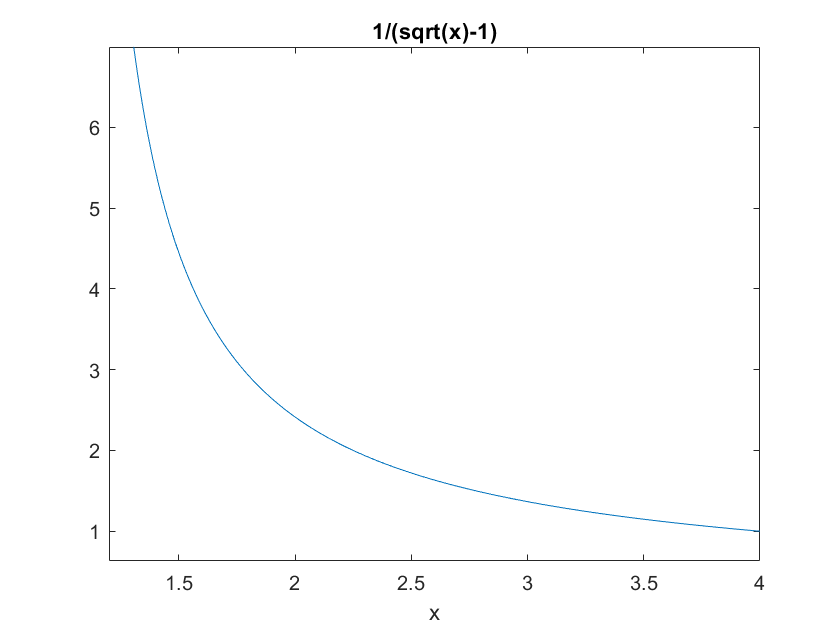

funrif2= @(x) 1./(sqrt(x)-1);
ezplot(funrif2,[1.2,4])

a2=1.2;
b2=4;



      ***Spiegazione di ciò che è stato fatto: ***

*Ho combinato due funzioni elementari oteenendo una nuova funzione composta in un intervallo scelto con ezplot.*

** 4.2. Considerare come valore esatto dell'integrale **$I=I[f]=\int_a^b f(x)dx$** il valore ottenuto mediante la funzione MATLAB **`integral`** con tolleranza **$10^{-9}$**;**

I = integral(funrif2, a2, b2, 'AbsTol', 1e-9);%calcolo l'integrale


     ***Spiegazione di ciò che è stato fatto: ***

*Ho calcolato l'integrale con la funzione integral di matlab e procedo fidandomi di quest'ultima.*

**4.3. Stimare l'integrale **$I$** utilizzando le principali formule di quadratura (Rect. sx, Rect. dx, Punto medio, Trapez., Simpson) su **$1, 2,$** e **$3$** nodi e calcolare per ognuna di esse il corrispondente errore di discretizzazione. **

Rs=(b2-a2) * funrif2(a2)% formula rettangolare sinistra

Rs =   29.336231610144672


Rd=(b2-a2) * funrif2(b2)% formula rettangolare sinistra

Rd =    2.800000000000000


Pm=(b2-a2) * funrif2((b2-a2)/2)% formula rettangolare sinistra

Pm =   15.282511696339462


T=((b2-a2)/2)  * (funrif2(a2) + funrif2(b2))%per dare maggior chiarezza dei pesi come a lezione (b-a)/2*(funrif(a2))+(b-a)/2*(funrif2(b2))

T =   16.068115805072335


S=((b2-a2)/6) * (funrif2(a2) + 4 * funrif2((b2-a2)/2) + funrif2(b2))% un fetta a sinistra 1 a destra e 4 al centro

S =   15.544379732583751


Errquadratura_Rs = abs(I-Rs);
Errquadratura_Rd = abs(I-Rd);
Errquadratura_Pm = abs(I-Pm);
Errquadratura_T = abs(I-T);
Errquadratura_S = abs(I-S); 
%creo la tabella
Tabella_Errori_Quadratura = table(Errquadratura_Rs,Errquadratura_Rd,Errquadratura_Pm,Errquadratura_T ,Errquadratura_S)

Tabella_Errori_Quadratura = 1×5 table
    Errquadratura_Rs    Errquadratura_Rd    Errquadratura_Pm    Errquadratura_T    Errquadratura_S 
    ________________    ________________    ________________    _______________    ________________

    22.8287140228866    3.70751758725804    8.77499410908142    9.5605982178143    9.03686214532571


%la simpson dovrebbe essere la più precisa invece non è così, 
% questo probabileente è perchè dipende dalla funzione e genera errore di randoff

    ***Spiegazione di ciò che è stato fatto: ***

*Ho calcolato approssimando l'integrale con le formule richieste dalla traccia ed affrontate a lezione, poi ho inserito in una tabella attraverso la funzione table() gli errori.*

** 4.4. Costruzione di formule di quadratura. Fissare **$p$ $3 \leq p \leq 5$** nodi distinti, non equispaziati, **$x_i \in [0,4]$**  di una formula di quadratura **

                                                                                   
$$Q[f]=w_1f(x_1)+w_2f(x_2)+\cdots+w_pf(x_p)$$
                            

**    per il calcolo numerico dell'integrale definito della funzione **$f$** in **$[0,4]$**;**

p=[0;1.4;3.1;4];
for i =2 :  4
    I_2 = I_2 + (p(i)-p(i-1))*funrif2(p(i));
end


***Spiegazione di ciò che è stato fatto: ***

*Per definire nodi non equispaziato ho generato tali nodi.*

**    4.5.  Determinare i valori dei pesi **$w_i$** affinché la formula risulti esatta per polinomi algebrici di grado al più **$p-1$** (costruire e risolvere il sistema **$B^Tw=I$**.)**

for i = 1 : 4
    l(i,1)=(4^i-0^i)/i;
end
V=[p.^0, p.^1, p.^2,p.^3];
w=Sgauss_pivot(V,l);% approssimazioni delle w
%la q esatta sarà
Qquadratura=0;
for i= 1 : 4
    Qquadratura=Qquadratura+w(i)*funrif2(p(i));
end



***Spiegazione di ciò che è stato fatto: ***

*Ho creato la formula di quadratura propria come mostrato a lezione, ma invece di aver generato la formula a mano l'ho generata attraverso un ciclo for eseguendo la sommatoria di w*funrif2.*